 clear
 % L1 = 0.215;
 % L2 = 0.15;
 % L3 = 0.44;
 % m1 = 0.25;
 % m2 = 0.15;
 % m3 = 0.15;
 L1 = 2.13;
 L2 = 1.5;
 L3 = 4.8;
 m1 = 2.5;
 m2 = 1.3;
 m3 = 1.3;
 % C1 = 0.05;
 % C2 = 0.02;
 % C3 = 0.01;
 C1 = 0.05;
 C2 = 0.0002;
 C3 = 0.0001;
 I1=(m1/12)*L1*L1;
 I2=(m2/12)*L2*L2;
 I3=(m3/12)*L3*L3;

 g=9.80665;
 % x1 = 0;
 % x2 = 0.2;
 % x3 = 0.1;
  x1 = 0;
 x2 = 0.002;
 x3 = 0.001;
 x1_dot = 0;
 x2_dot = 0;
 x3_dot = 0;

load('matrix.mat')

A=Ae(x1, I1, x1_dot, x2, I2, x2_dot, x3, I3, x3_dot,L1, L2, L3, m1, m2, m3, 0, g, C1, C2, C3);
B=Be(x1, I1, x1_dot, x2, I2, x2_dot, x3, I3, x3_dot,L1, L2, L3, m1, m2, m3, 0, g, C1, C2, C3);
A = double(A)

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0    8.5158   -1.0648   -0.0091   -0.0001    0.0000
         0   23.9530  -10.3496   -0.0167   -0.0002    0.0002
         0  -26.4482   17.5567    0.0184    0.0003   -0.0002


B = double(B)

B =          0
         0
         0
    0.1829
    0.3340
   -0.3688


C = [1,0,0,0,0,0]

C =      1     0     0     0     0     0


D = 0

D = 0

y = ss(A,B,C,D)

y =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           0           0           1           0           0
   x2           0           0           0           0           1           0
   x3           0           0           0           0           0           1
   x4           0       8.516      -1.065   -0.009147   -6.68e-05   3.688e-05
   x5           0       23.95      -10.35     -0.0167  -0.0002392   0.0001534
   x6           0      -26.45       17.56     0.01844   0.0003068  -0.0002108
 
  B = 
            u1
   x1        0
   x2        0
   x3        0
   x4   0.1829
   x5    0.334
   x6  -0.3688
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


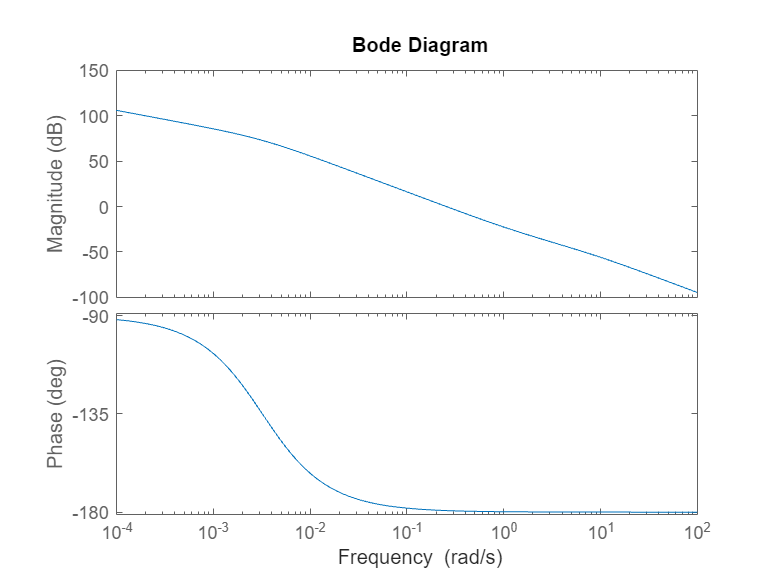

figure;           
bode(y)

G = tf(y)

G =
 
     0.1829 s^4 + 4.641e-05 s^3 - 4.357 s^2 - 0.0001294 s + 9.425
  ------------------------------------------------------------------
  s^6 + 0.009597 s^5 - 41.51 s^4 - 0.2199 s^3 + 146.8 s^2 + 0.4713 s
 
Continuous-time transfer function.
Model Properties


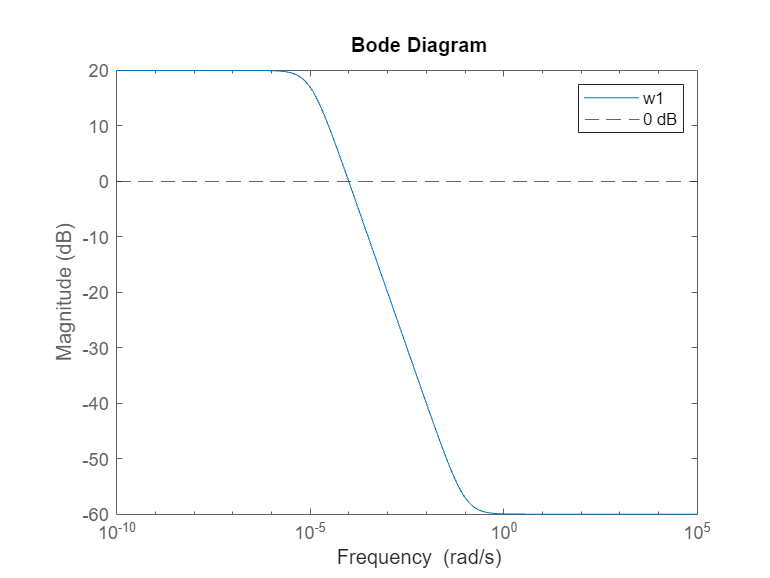

w1 = makeweight(10,[0.01,0.01],0.001);
w2 = 0;
w3 = 0;
% w1 = makeweight(0.1,[0.001,0.005],0.0001);
% w2 = 0;
% w3 = 0;
% w1 = makeweight(0.01,[0.01,0.005],0.0001);
% w2 = 0;
% w3 = makeweight(0.00001,[0.01,0.0005],0.001);
% figure
% bodemag(w1)
% yline(0,'--');
% legend('W1','0 dB')
% w1 = makeweight(500,[0.05,0.02],0.003);
% w2 = 0;
% w3 = makeweight(0.5,[1,20],400);
% 
figure
bodemag(w1,{1e-10, 1e5})
yline(0,'--');

% yline(0,'--');
legend('w1','0 dB')

P = augw(G,w1,w2,w3)

P =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7
   x1   -9.95e-06           0  -0.0001787  -2.266e-08   0.0005319   3.159e-08   -0.004602
   x2           0   -0.009597       5.189     0.01374      -2.294    -0.01473           0
   x3           0           8           0           0           0           0           0
   x4           0           0           2           0           0           0           0
   x5           0           0           0           4           0           0           0
   x6           0           0           0           0         0.5           0           0
   x7           0           0           0           0           0         0.5           0
 
  B = 
             u1        u2
   x1  0.007812         0
   x2         0         1
   x3         0         0
   x4         0         0
   x5         0         0
   x6         0         0
   x7         0         0
 
  C = 
               x1          x2          x3


nmeas=1;
ncont=1;
[K,CL,gamma] = hinfsyn(P,nmeas,ncont)

K =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7
   x1   -9.95e-06   1.305e-19   1.071e-11   1.357e-15  -3.189e-11   2.802e-15    2.76e-10
   x2   9.682e+05      -179.3       -2318  -1.131e+04    -1.1e+04  -4.217e+04  -6.058e+04
   x3       61.57           8      -443.2    -0.05612        1319     -0.1159  -1.142e+04
   x4       24.92  -2.185e-06      -177.4    -0.02272         534    -0.04692       -4621
   x5       26.05  -2.284e-06      -187.5       3.976       558.3    -0.04905       -4831
   x6       4.604  -4.036e-07      -33.14   -0.004196       99.15   -0.008667      -853.7
   x7       1.003  -8.793e-08       -7.22  -0.0009143        21.5      0.4981        -186
 
  B = 
               u1
   x1    0.007813
   x2   -1.37e+04
   x3  -1.938e+04
   x4       -7843
   x5       -8199
   x6       -1449
   x7      -315.7
 
  C = 
               x1          x2          x3          x4          x5          x6          x7
   y1   9.682e+

gamma = 0.0685

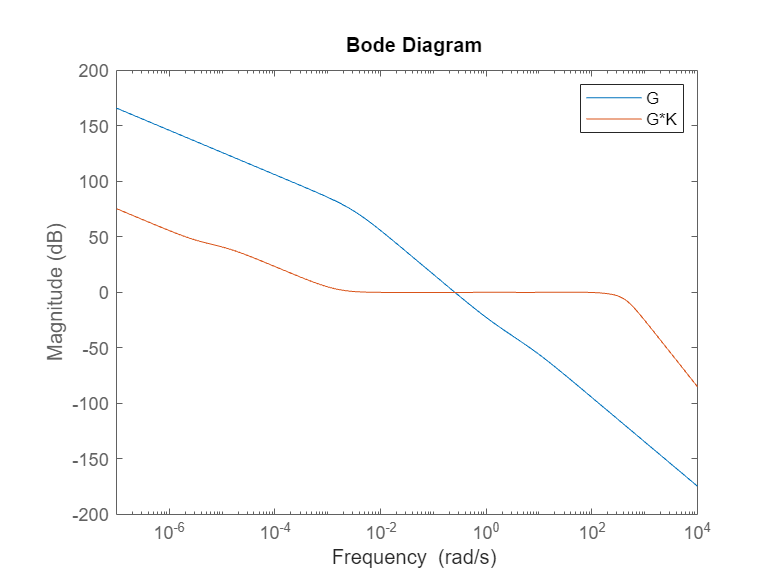


figure;
bodemag(G,G*K)
legend('G','G*K')

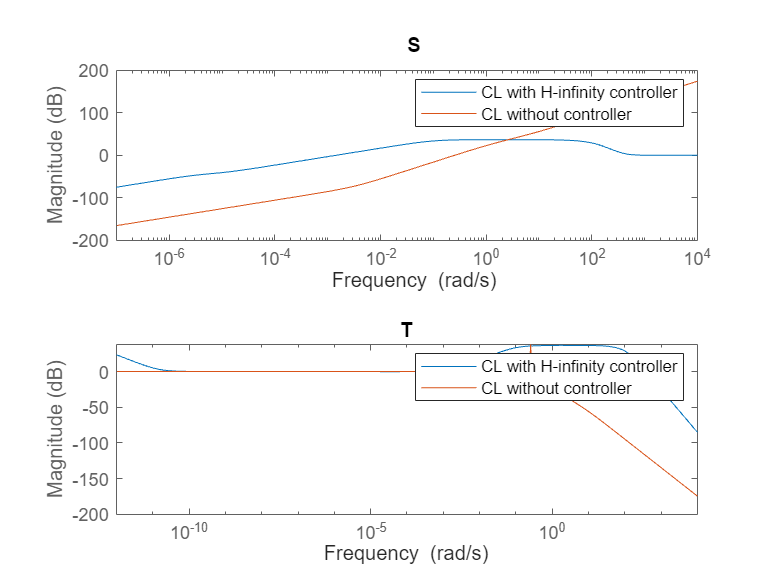

subplot(2,1,1)
bodemag(1/(1+G*K),1/G)
legend('CL with H-infinity controller','CL without controller')
title('S')

subplot(2,1,2)
bodemag((G*K)/(1+G*K),G/(1+G))
legend('CL with H-infinity controller','CL without controller')
title('T')



A_c = K.A;
B_c = K.B;
C_c = K.C;
D_c = K.D;
save controler A_c B_c C_c D_c

sim('untitled4.slx')